# UNSUPERVISED LEARNING

1.  load the iris data set with the command `load 'fisheriris'`.  Two data structures will appear in your workspace: `meas` and `species`.  The data structure `meas` contains the flower measurements as a 150x4 matrix -- 150 samples, each with 4 variables.  The data structure `species` has text labels for each iris type; these labels are not needed for the clustering exercises here.  

load fisheriris
meas

meas =           5.1          3.5          1.4          0.2
          4.9            3          1.4          0.2
          4.7          3.2          1.3          0.2
          4.6          3.1          1.5          0.2
            5          3.6          1.4          0.2
          5.4          3.9          1.7          0.4
          4.6          3.4          1.4          0.3
            5          3.4          1.5          0.2
          4.4          2.9          1.4          0.2
          4.9          3.1          1.5          0.1


2.  Cluster the iris data set using `kmeans` and create a dendrogram using using matlab's `linkage.m`. Compare the results.

[idx, C] = kmeans(meas,3)

idx =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


C =          6.85       3.0737       5.7421       2.0711
       5.9016       2.7484       4.3935       1.4339
        5.006        3.428        1.462        0.246


% Correction
idx = kmeans(meas,3,"Distance","cityblock","Replicates",5)

idx =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


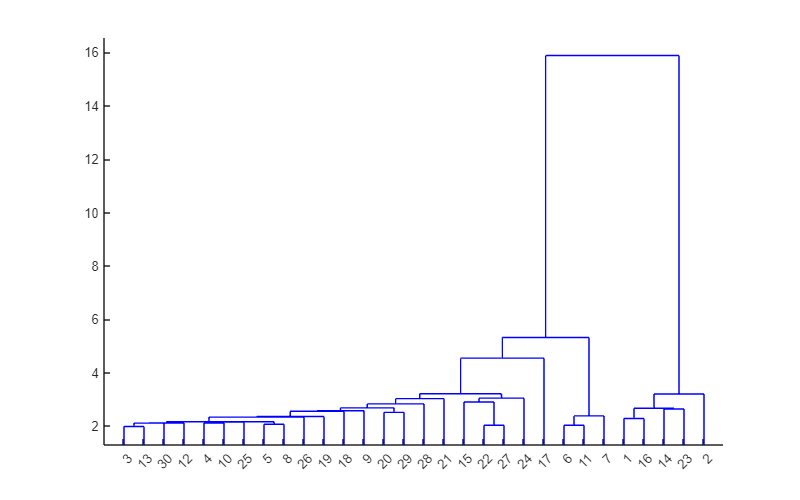


d = pdist(meas);
m = squareform(d);
ml = linkage(m);
dendrogram(ml)

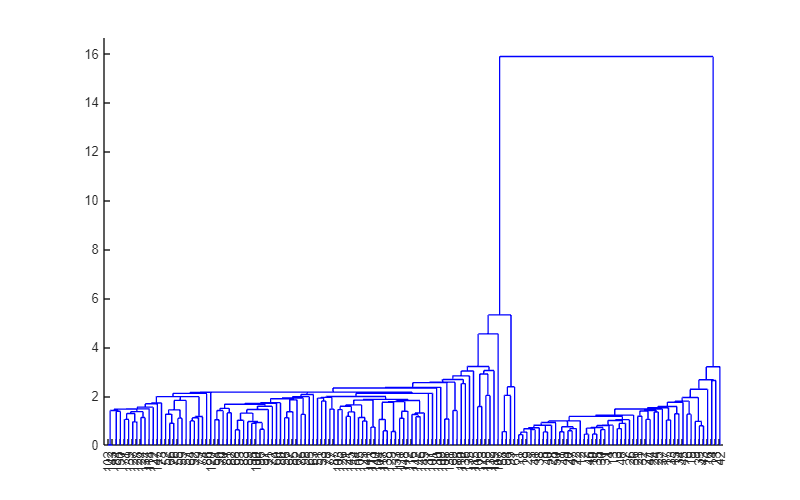

% Correction: putt 150 leaves
dendrogram(ml,150)

3.  Run `origbcm.m` on a dataset of 8 normalized random vectors.  Comment on the result.

rs = 0;
p8data = .7*ones(8)+.3*eye(8);
p8data = normc(p8data);

'normc' requires Deep Learning Toolbox.

p8data'*p8data
b0 = initorigbcm(8,2,rs)
bf = origbcm(b0,p8data,100000,.005,rs)
bf.wts*p8data
% Correction:
ni=initorigbcm(8,2,rs)
pats=normc(rand(8))
pats'*pats
nf=origbcm(ni,pats,2000000,.002,rs)
nf.wts*pats% responese for pattern

# LANGUAGE

Create an SRN model of the grammar below.  Generate a list of training strings. 

Test the model on grammatical strings, such as BPXXRJXXXRQE

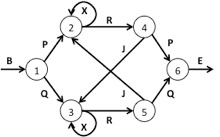

% setup list generation

reber.ind = [ % col->row weight
    0 1 0 0 0 0 0 0;
    0 0 2 3 0 0 0 0;
    0 0 4 0 5 0 0 0;
    0 0 0 4 0 5 0 0;
    0 0 0 6 0 0 2 0;
    0 0 6 0 0 0 3 0;
    0 0 0 0 0 0 0 7;
    0 0 0 0 0 0 0 0;];
reber.prob = [ % 0.5 for two output, 1 for one output
    0    1    0    0    0    0    0    0;
    0    0    0.5  0.5  0    0    0    0;
    0    0    0.5  0    0.5  0    0    0;
    0    0    0    0.5  0    0.5  0    0;
    0    0    0    0.5  0    0    0.5  0;
    0    0    0.5  0    0    0    0.5  0;
    0    0    0    0    0    0    0    1.0;
    0    0    0    0    0    0    0    0;];
reber.labels = 'BPQXRJE';

% init net
n0=initnet3srnx(8,12,8,2,2,rs)

% make training list
list2k = makestringlist(reber,2000)
% train net
nf=bp3srn(n0,list2k,30000,0.02,0)
% BPXXRJXXXRQE = 124456444537
[s h s2]=stringprocv4X(nf,[1 2 4 4 5 6 4 4 4 5 3 7],reber)

% Correction: fixed hidlayersrn() 
plot3(h(:,1),h(:,2),h(:,3))
hold on
scatter3(h(:,1),h(:,2),h(:,3))


## Attachments

function babynet = initorigbcm( nin,range,rs )
%initialize bcm cell
rng(rs);
babynet.wts=range*(rand(1,nin)-0.5) ;
babynet.rb = 0 ;
end

function finalcell = origbcm( initcell, pset, niter, dt, rs )
%iterates iterbcm
cell=initcell;
avgpat=sum(pset,2)/size(pset,2);
rng(rs) ;
for i=1:niter
    apat = pset(:,irand(size(pset,2),1)) ;
    r=cell.wts*apat ;
    cell.rb = cell.wts*avgpat ;
    cell.wts = cell.wts + dt*r*(r-cell.rb*cell.rb)*apat' ;
end
finalcell=cell;
end

% SRN

% Generate strings
function strings = makestringlist(tgram,nstrings)
jj=1; % initial state
strings.list=[];
strings.states=[];
nstates=size(tgram.prob,2);
for ii=1:nstrings
    strings.ind(ii)=jj ; %index into superstring
    seq=[]; %initialize one string
    st=1;
    stlist=[] ; %initial state list
    while (st<nstates)
        rr=rand();
        cumu=0; i=0;
        while (cumu<rr)
            i=i+1;
            cumu=cumu+tgram.prob(st,i);
        end
        letter=tgram.ind(st,i) ;
        seq=[seq letter];
        stlist=[stlist st];
        st=i;
    end
    seq=[seq nstates] ; % append end character to seq
    strings.list=[strings.list seq];
    jj=jj+size(seq,2);
    strings.states=[strings.states stlist];
end
end



% Initialize weights
function netstruct=initnet3srnx(n1,n2,n3,uamp,vamp,rs)
rng(rs);
netstruct.wih=uamp*(rand(n2,n1)-0.5) ;
netstruct.hh=uamp*(rand(n2,n2)-0.5) ;
netstruct.hbias=uamp*(rand(1,n2)-0.5) ;
netstruct.whout=vamp*(rand(n3,n2)-0.5) ;
netstruct.obias=vamp*(rand(1,n3)-0.5);
netstruct.context=zeros(1,n2);
end

% Main program
function finalnet=bp3srn(net0,strlist,niter,eta,nlev)
netk=net0;
for i=1:niter
    ts=selectstring(strlist) ; % choses a new string from the training set
    netk.context=zeros(1,size(netk.wih,1)); % rests the context for a new string
    for j=1:size(ts,2)-1 % this loop trains a single string
        netk=cyc3srn(netk,ts(j),ts(j+1),eta,nlev) ;
    end
end
finalnet=netk;
end


% chose training string
function sg = selectstring(sdata)
j=randi(size(sdata.ind,2)) ;
if (j<size(sdata.ind,2)) sg=sdata.list(sdata.ind(j):sdata.ind(j+1)-1);
else sg=sdata.list(sdata.ind(j):size(sdata.list,2)) ;
end
end


% Computes activities
function netact=forw1p3srn(netwk,p,nois)
netact.hid=hidlayersrn(p,netwk.context,netwk.wih,netwk.hh,netwk.hbias,nois);
netact.out=layersig01(netact.hid,netwk.whout,netwk.obias) ;
end


% Computes errors and adjusts weights
function newstruct=cyc3srn(nstruct,pin,pout,dt,noi)
newstruct=nstruct;
activity=forw1p3srn(nstruct,pin,noi) ;
tvec=zeros(size(nstruct.obias)) ;
tvec(pout)=1;
odelt=tvec-activity.out; %output deltas
hdelt=0.5*(nstruct.whout'*odelt').*(1+activity.hid').*(1-activity.hid');%hid deltas
%adjust weights and biases
newstruct.whout=newstruct.whout+dt*odelt'*activity.hid ;
newstruct.obias=newstruct.obias+dt*odelt ;
newstruct.wih(:,pin)=newstruct.wih(:,pin)+dt*hdelt; %just update weights from active input
newstruct.hbias=newstruct.hbias+dt*hdelt' ;
newstruct.hh=newstruct.hh+dt*hdelt*nstruct.context ;
newstruct.context=activity.hid ;
end



function [sout,hlist,slist] = stringprocv4X(netwk,strg,gramm)
hlist=[] ;
ctxinp=zeros(1,size(netwk.wih,1));
slist=[] ;
lets=gramm.labels(strg)

%STRINGS!!!
s1=[] ;
sout=[];

for j=1:size(strg,2)-1
    hhh=hidlayersrn(strg(j),ctxinp,netwk.wih,netwk.hh,netwk.hbias,0.0);
    ou=layersig01(hhh,netwk.whout,netwk.obias);
    hlist=[hlist;hhh] ;
    s1=[s1,lets(j)];
    scell=cellstr(s1) ;
    slist=[slist;scell] ;
    sout=[sout, sprintf('%c %c',gramm.labels(strg(j)), gramm.labels(strg(j+1)))] ;
    for kk=1:size(netwk.whout,1)
        sout=[sout sprintf('%6.3f',ou(kk))];
    end
    sout=[sout, sprintf('\n')];

    ctxinp=hhh;
end
end

function lout=hidlayersrn(pin,ctx,win,wctx,b,noise)
lll=b'+win(:,pin)+wctx*ctx';% FIXED %combine input from single input and ctx layer
lout=sigpn(lll)'+noise*(rand(size(lll))'-0.5);
end